**Problem 1**

If an input to an LTI system is x_n and the output is y_n

syms n
x(n) = ((1/9)^n)*heaviside(n)+(2^n)*heaviside(-n-1)

$$x(n) = {\left(\frac{1}{9}\right)}^{n}\,\mathrm{heaviside}\left(n\right)+2^{n}\,\mathrm{heaviside}\left(-n-1\right)$$

y(n) = (5*(1/3)^n)*heaviside(n)-5*((2/3)^n)*heaviside(n-1)

$$y(n) = 5\,{\left(\frac{1}{3}\right)}^{n}\,\mathrm{heaviside}\left(n\right)-5\,{\left(\frac{2}{3}\right)}^{n}\,\mathrm{heaviside}\left(n-1\right)$$

A) Find the system transfer function H(z). Plot the poles, zeros, and ROC

syms z
X(z) = ztrans(x,n,z)

$$X(z) = \frac{1}{9\,z-1}+\frac{1}{2}$$

Y(z) = ztrans(y,n,z)

$$Y(z) = \frac{5}{3\,z-1}-\frac{10\,\left(\frac{1}{\frac{3\,z}{2}-1}+\frac{1}{2}\right)}{3\,z}+\frac{5}{2}$$

H(z) = simplify(Y/X)

$$H(z) = -\frac{5\,\left(18\,z-2\right)\,\left(-27\,z^{3}+27\,z^{2}+12\,z-4\right)}{6\,z\,\left(9\,z+1\right)\,\left(9\,z^{2}-9\,z+2\right)}$$

Poles and zeros:

[num, den] = numden(H)

$$num(z) = -5\,\left(9\,z-1\right)\,\left(-27\,z^{3}+27\,z^{2}+12\,z-4\right)$$

$$den(z) = 3\,z\,\left(9\,z+1\right)\,\left(9\,z^{2}-9\,z+2\right)$$

poles = solve(den==0)

$$poles = \left(\begin{array}{c} -\frac{1}{9}\\ 0\\ \frac{1}{3}\\ \frac{2}{3} \end{array}\right)$$

%zeros = simplify(solve(n==0))
zeros = [1/9 -0.496429523937 0.236943817851 1.25948570609]

zeros =     0.1111   -0.4964    0.2369    1.2595


I couldn't figure out how to do an ROC in matlab, so here is a picture of one I did by hand. From the textbook table, I determined the ROC constrains to be

z >= 1/9, z <= 2, z >= 1/3, and z <= 2/3. With these cosntrains we can see that the ROC looks like this:

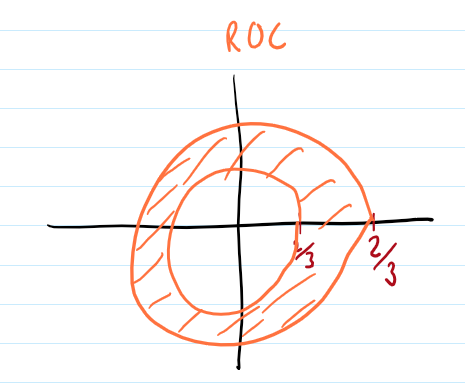

B) Find the impulse response of the system in the [n] domain

h(n) = iztrans(H,z,n)

$$h(n) = 5\,{\left(\frac{1}{3}\right)}^{n}-\frac{10\,\delta_{n-1,0}}{3}-\frac{50\,{\left(\frac{2}{3}\right)}^{n}}{7}-\frac{335\,{\left(-\frac{1}{9}\right)}^{n}}{7}+55\,\delta_{n,0}$$

C) Find the difference equation that describes the input-output relationship

What's the difference between that and (B)?

D) Is the system stable and is it causal? Justify.

The system is not stable because the ROC doesn't use the ring with diameter greater than the largest pole. It is causal though, because the difference equation has no positive time shifts which would cause it to respond to an input before it happens.

**Problem 2**

An LTI system has the frequency response:

syms w
s = exp(-i*w)

$$s = {\mathrm{e}}^{-w\,\mathrm{i}}$$

H = (1-s^2)/(1-(5/6)*s+(1/6)*s^2)

$$H = -\frac{{\mathrm{e}}^{-2\,w\,\mathrm{i}}-1}{1+\frac{{\mathrm{e}}^{-2\,w\,\mathrm{i}}}{6}-\frac{5\,{\mathrm{e}}^{-w\,\mathrm{i}}}{6}}$$

I'm going to re-express this in the laplace domain to take advantage of some of matlab's tools.

clear s
syms s
H_tf = tf([-1 0 1],[1/6 -5/6 1])

H_tf =
 
          -s^2 + 1
  -------------------------
  0.1667 s^2 - 0.8333 s + 1
 
Continuous-time transfer function.



H(s) = (1-s^2)/(1-5*s/6+(s^2)/6)

$$H(s) = -\frac{s^{2}-1}{\frac{s^{2}}{6}-\frac{5\,s}{6}+1}$$

A) Determine the output y(n) if the input

syms n
% input equation
x(n) = sin(pi*n/6)

$$x(n) = \sin\left(\frac{\pi \,n}{6}\right)$$

% convert to laplace domain
X(s) = laplace(x)

$$X(s) = \frac{\pi }{6\,\left(s^{2}+\frac{\pi^{2}}{36}\right)}$$

% output
output = simplify(ilaplace(X*H, n))

$$output = \begin{array}{l} \frac{108\,\pi \,{\mathrm{e}}^{2\,n}}{\pi^{2}+144}-\frac{288\,\pi \,{\mathrm{e}}^{3\,n}}{\pi^{2}+324}+\frac{46656\,\sigma_{1}+6480\,\pi \,\sigma_{2}+180\,\pi^{3}\,\sigma_{2}+1080\,\pi^{2}\,\sigma_{1}-6\,\pi^{4}\,\sigma_{1}}{\left(\pi^{2}+144\right)\,\left(\pi^{2}+324\right)}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,n}{6}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,n}{6}\right) \end{array}$$

B) Find the inpulse response h(n)

h(n) = ilaplace(H,n)

$$h(n) = 18\,{\mathrm{e}}^{2\,n}-48\,{\mathrm{e}}^{3\,n}-6\,\delta (n)$$

C) Find the frequency response for

expres1(n)=(n+1)*h

$$expres1(n) = -\left(n+1\right)\,\left(48\,{\mathrm{e}}^{3\,n}-18\,{\mathrm{e}}^{2\,n}+6\,\delta (n)\right)$$

Express1 = laplace(expres1)

$$Express1 = \frac{6\,\left(-s^{4}+5\,s^{3}-10\,s^{2}+9\,s+1\right)}{{\left(s-2\right)}^{2}\,{\left(s-3\right)}^{2}}$$

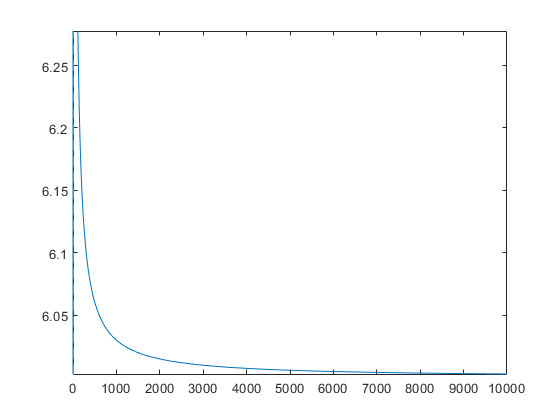

figure; fplot(abs(Express1), [0 10000])

D) Find the difference equation for the input-output relationship for this system.

%Convert from laplace to time domain
h = ilaplace(H, n)

$$h = 18\,{\mathrm{e}}^{2\,n}-48\,{\mathrm{e}}^{3\,n}-6\,\delta (n)$$

%convert from time domain to z domain
hz = ztrans(h)

$$hz = \frac{18\,z}{z-{\mathrm{e}}^{2}}-\frac{48\,z}{z-{\mathrm{e}}^{3}}-6\,\mathrm{ztrans}\left(\delta (n),n,z\right)$$

%convert from z domain back to time domain
h = iztrans(hz)

$$h = 48\,{\mathrm{e}}^{3}\,\left({\mathrm{e}}^{-3}\,\delta_{n,0}-{\mathrm{e}}^{-3}\,{\left({\mathrm{e}}^{3}\right)}^{n}\right)-18\,{\mathrm{e}}^{2}\,\left({\mathrm{e}}^{-2}\,\delta_{n,0}-{\mathrm{e}}^{-2}\,{\left({\mathrm{e}}^{2}\right)}^{n}\right)-6\,\delta (n)-30\,\delta_{n,0}$$